# Clamped bar implementation

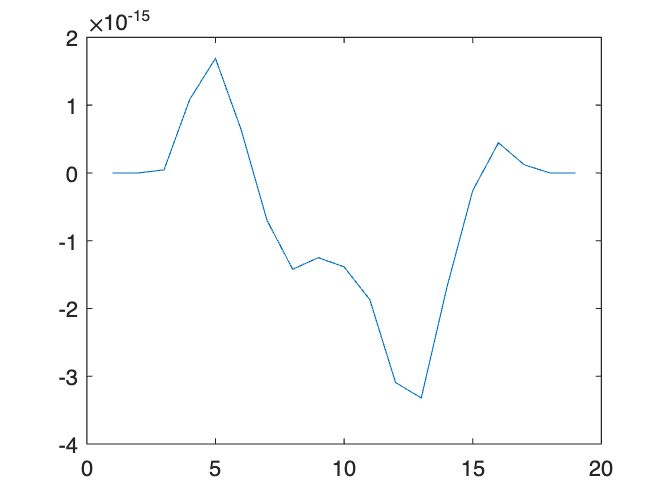

% Simon Andersen
% sand22@student.aau.dk

clc;
% marimba params
L = 0.473;                      % length
rho = 7850;                     % material density (rosewood): 7850 or 800
E = 2.45387e+13;                % Young's modulus
I = 4.91e-14;                   % moment of inertia
A = 7.85e-07;                   % cross-sectio nal area  

% damping params
sigma0 = 0.2;                   % first damping term: 0.2 or 5
sigma1 = 0.0697;                % second damping term: 0.0697 or 25

% system params
fs = 44100;                     % sample rate
f0 = 440;                       % fundamental frequency
seconds = 1;                    % length of audio
lengthSound = fs * seconds;     % samples for calculation

kappa = sqrt((E*I)/(rho*A));    % stability condition

k = 1/fs;                       % temporal step size
c = 2 * L * f0;                 % wave speed
h = sqrt(2 * kappa * k);        % spatial time step 
N = floor(L/h);                 % the actual time step that we use 
h = L/N;                        % recalculation of h

% array initialization
uNext = zeros(N+1,1);           % next time step
u = zeros(N+1,1);               % current time step
uPrev = zeros(N+1,1);           % previous time step

% exitation
u(3:9) = hann(7);               % applying hanning window as excitation
uPrev = u;                      % copy value for calculation

% output initialization
out = zeros(lengthSound, 1);    % waveform
outIx = round((N+1)/3);         % listening point

% Time integration loop
for j = 1:lengthSound
    % Compute displacement for the clamped bar
    for l = (3:N-1)       
        uNext(l) = (2 * u(l) - uPrev(l)) / (1 + 2 * sigma0 * ...
            (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) ...
            * (u(l+2) - 4*u(l+1) + 6*u(l) - 4*u(l-1) + u(l-2)) + ...
            (2 * sigma1 / k * h^2) * (u(l+1) - 2 * u(l) + u(l-1) ...
            - uPrev(l + 1) + 2 * uPrev(l) - uPrev(l - 1)));
    end

    % Store the output (from the physical domain)
    out(j) = uNext(outIx);

    % Update uPrev and u for next time step
    uPrev = u;
    u = uNext;
    
    %plot(uNext);
    %plot(out);
    %drawnow;
    
end

plot(uNext);

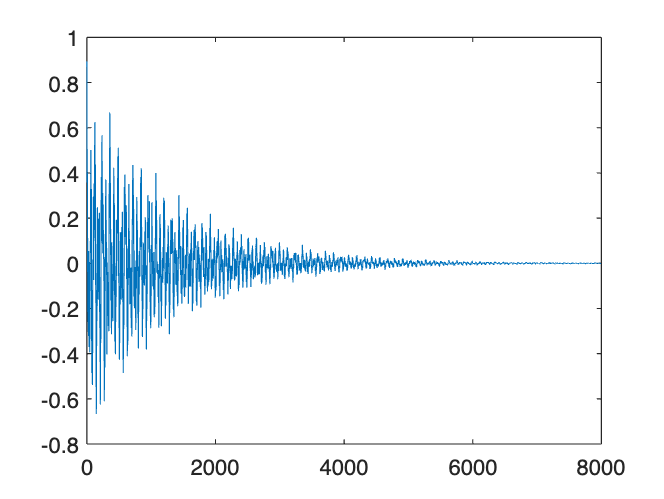

plot(out);
xlim([0 8000]); 

soundsc(out, fs);               % preview sound

filename = 'clamped.wav';

% Export the audio data to a WAV file
audiowrite(filename, out, fs);

% Confirm the file was written
disp(['Audio data has been written to ' filename]);

Audio data has been written to clamped.wav
